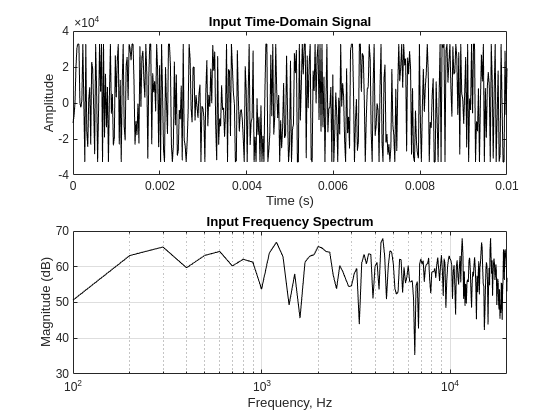

% Load the WAV file
[in, fs] = audioread('in_white_noise_10ms.wav', 'native'); % signal is the audio data, fs is the sample rate

% Plot the time-domain signal
t = (0:length(in)-1) / fs;
figure;
subplot(2,1,1);
plot(t, in, Color="black");
xlabel('Time (s)');
ylabel('Amplitude');
title('Input Time-Domain Signal');

% Compute and plot the spectrum with log frequency axis
n = length(in);
frequencies = (0:n-1) * (fs/n); 
in_zp = [zeros([256,1]); in; zeros([256,1])];
spectrum = fft(in_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)), Color="black");
xlim([0,20000]);
xlabel('Frequency, Hz');
ylabel('Magnitude (dB)');
title('Input Frequency Spectrum');
grid;

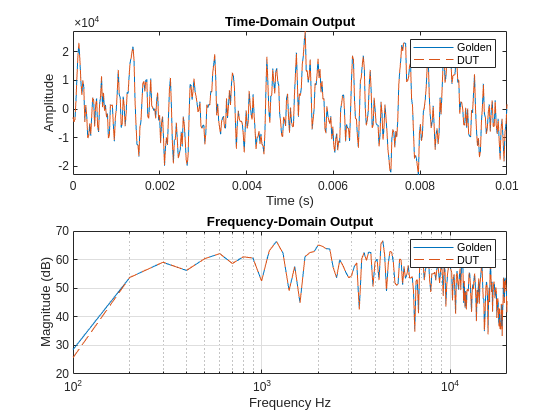

% ---------- GOLDEN vs DUT ----------
% Load the WAV files
[out_golden, fs] = audioread('golden_out.wav', 'native'); % signal is the audio data, fs is the sample rate
[out_dut, fs] = audioread('dut_out.wav', 'native');

% Plot the time-domain signal
figure;
subplot(2,1,1);

t = (0:length(out_golden)-1) / fs;
plot(t, out_golden);
hold on;
t = (0:length(out_dut)-1) / fs;
plot(t, out_dut, '--');

xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Output');
legend('Golden', 'DUT');
hold off;

% Compute and plot the spectrum with log frequency axis
n = length(out_golden);
frequencies = (0:n-1) * (fs/n); 
out_golden_zp = [zeros([256,1]); out_golden; zeros([256,1])];
spectrum = fft(out_golden_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)));

hold on;

n = length(out_dut);
frequencies = (0:n-1) * (fs/n); 
out_dut_zp = [zeros([256,1]); out_dut; zeros([256,1])];
spectrum = fft(out_dut_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)), '--');

xlim([0,20000]);
xlabel('Frequency Hz');
ylabel('Magnitude (dB)');
title('Frequency-Domain Output');
grid;
legend('Golden', 'DUT');
hold off;


total_sample_diff = sum(out_golden - out_dut)

total_sample_diff = 11118

average_sample_diff = total_sample_diff / n

average_sample_diff = 25.1538

% currdata = typecast(0x000013CD, 'int32')
% prevdata = typecast(0x00000000, 'int32');
% decay = 512;
% data_o = currdata + bitshift(decay*(prevdata - currdata), -10,"int32")
% data_o_hex = dec2hex(data_o)
% data_o_bin = dec2bin(data_o,16)
% 
% received = 0x00

% ---------- GOLDEN vs DUT ----------
% Load the WAV files
[out_golden, fs] = audioread('golden_out_LP_512_x2_HP_100_x2_white_noise_10ms.wav', 'native'); % signal is the audio data, fs is the sample rate

% Plot the time-domain signal
figure;
subplot(2,1,1);

t = (0:length(out_golden)-1) / fs;
plot(t, out_golden);
hold on;
t = (0:length(out_dut)-1) / fs;
plot(t, out_dut, '--');

xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Output');
legend('Golden', 'DUT');
hold off;

% Compute and plot the spectrum with log frequency axis
n = length(out_golden);
frequencies = (0:n-1) * (fs/n); 
out_golden_zp = [zeros([256,1]); out_golden; zeros([256,1])];
spectrum = fft(out_golden_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
subplot(2,1,2);
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)));

hold on;

n = length(out_dut);
frequencies = (0:n-1) * (fs/n); 
out_dut_zp = [zeros([256,1]); out_dut; zeros([256,1])];
spectrum = fft(out_dut_zp);
magnitude_dB = 20 * log10(abs(spectrum) / n); % Magnitude in dB

% Plot using a logarithmic frequency axis
semilogx(frequencies(1:floor(n/2)), magnitude_dB(1:floor(n/2)), '--');

xlim([0,20000]);
xlabel('Frequency Hz');
ylabel('Magnitude (dB)');
title('Frequency-Domain Output');
grid;
legend('Golden', 'DUT');
hold off;

total_sample_diff = sum(out_golden - out_dut)
average_sample_diff = total_sample_diff / n